# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{
    
    run_ge.mlx
    ----------

    This code runs all codes to solve the decentralized model.
	
%}

## Model: Decentralized Model.

The model is solved as decentralized problem. The household's problem is


$$\underset{\{c_t\}_{t=0}^{\infty},\{a_{t+1}\}_{t=0}^{\infty}}{\text{max }} \mathbb{E}_0 \sum_{t=0}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\text{s.t. } c_t + a_{t+1} = (1+r)a_t + wl_te^{z_t} \ ,$$


 
$$z_{t+1} = \mu + \rho z_t + \epsilon_{t+1} \end{array} \ ,$$



$$c_t > 0 \ , \\
a_t \geq \phi \ , $$



$$a_t \ \text{is given} \ ,$$


where $w$ is the wage rate that households take as given, $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints hold for $t = 1, 2, ...,$. The firm's problem is static and given by


$$\underset{k_t,l_t}{\text{max }} k_t^{\alpha}l_t^{1-\alpha} - wl_t - r_tk_t \text{ ,}$$


 
$$\text{s.t.} \ k_{t+1} = (1-\delta)k_t + i_t \ .$$


Firms are perfectly competitive so prices are


$$r = \alpha k_t^{\alpha-1}l_t^{1-\alpha}-\delta \ ,$$



$$w = (1-\alpha)k^{\alpha} l^{\alpha}\ .$$


Normalizing labor supply such that $l_t = 1$, prices in steady state (where variables have "settled down") are


$$y^* = {k^*}^{\alpha} \ , \\
i^* = \delta k^* \ ,$$



$$r = \alpha {k^*}^{\alpha-1}-\delta \ ,$$



$$w = (1-\alpha){k^*}^{\alpha} \ .$$


In the steady-state equilibrium, the asset market clears so the saving supplied by households equals the capital demanded by firms


$$k = \int a(z,r,w) \ dF(a) \approx \sum_{i=1}^N a_i(z,r,w) \ .$$


The equilibrium consists of (i) optimal policy functions given $r$ and $w$, (ii) steady-state distributions consistent with the optimal policy functions, and (iii) labor and captial markets clearing.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:\Users\USER\Documents\GitHub\Notes-Dynamic-Macro_-Group-7\Linear Tax'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\USER\Documents\GitHub\Notes-Dynamic-Macro_-Group-7\Linear Tax 



## Set the parameters and generate the state space.

Note that the firm's problem is static and if we are able to solve for $r$, then we can back out $k$ and solve for $w$.

Calls: model.m.

% Initialize model
par = lmodelwithtax.setup();
par = lmodelwithtax.gen_grids(par);
%sol = struct();

## Solve the model in partial equilibrium.

Solve the model taking prices as given but with out checking if markets clear, then plot the distribution of wealth.

Calls: solve.m, simulate.m, my_graph.m

% Solve firm problem
[par, sol] = lsolvewithtax.firm_problem(par); % Firms.

% Solve household problem
sol = lsolvewithtax.hh_problem(par, sol); % Households.

------------Beginning Backward Induction.------------

Adjusted flat tax: tau = 0.2000
Solving for age 3
Solving for age 2
Solving for age 1
------------Backward Induction Complete.------------

Welfare (overall): -1.3539
Welfare (low-skill): -1.3741
Welfare (high-skill): -1.3338



% Simulate the economy
sim = lsimulate.economy(par, sol); % Simulate the economy.

Number of low-skill agents: 45
Number of high-skill agents: 55
Agent 1, Skill 2, Savings: 0.6012, Labor: 1.0000
Agent 2, Skill 1, Savings: 0.6012, Labor: 1.0000
Agent 3, Skill 1, Savings: 0.6012, Labor: 1.0000
Agent 4, Skill 2, Savings: 0.7415, Labor: 1.0000
Agent 5, Skill 2, Savings: 0.7415, Labor: 1.0000
Agent 6, Skill 2, Savings: 0.6012, Labor: 1.0000
Agent 7, Skill 1, Savings: 0.5010, Labor: 1.0000
Agent 8, Skill 2, Savings: 0.7415, Labor: 1.0000
Agent 9, Skill 1, Savings: 0.6012, Labor: 1.0000
Agent 10, Skill 1, Savings: 0.6012, Labor: 1.0000
Agent 11, Skill 2, Savings: 0.7415, Labor: 1.0000
Agent 12, Skill 1, Savings: 0.6012, Labor: 1.0000
Agent 13, Skill 2, Savings: 0.6012, Labor: 1.0000
Agent 14, Skill 1, Savings: 0.6012, Labor: 1.0000
Agent 15, Skill 2, Savings: 0.5010, Labor: 1.0000
Agent 16, Skill 2, Savings: 0.7415, Labor: 1.0000
Agent 17, Skill 1, Savings: 0.5010, Labor: 1.0000
Agent 18, Skill 1, Savings: 0.6012, Labor: 1.0000
Agent 19, Skill 2, Savings: 0.7415, Labor: 1.0

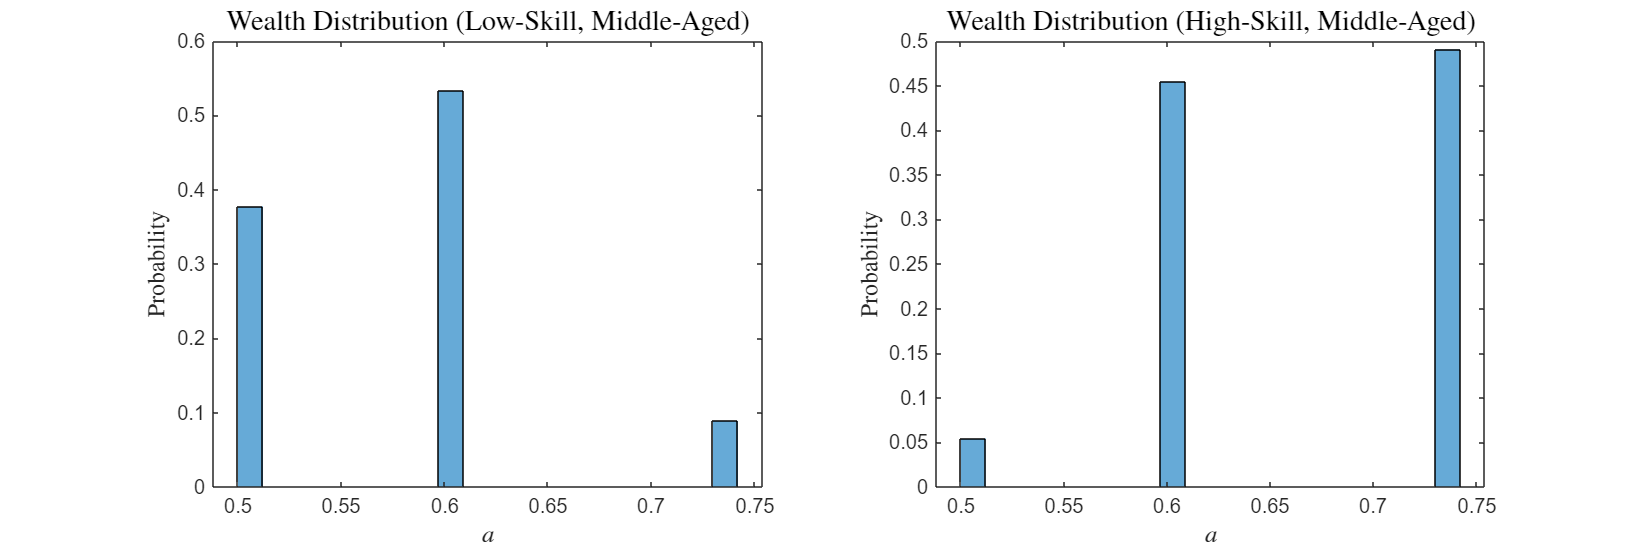

%Generate Plots
lmy_graph.plot_dist(par, sol, sim) % Plot the distribution of wealth.

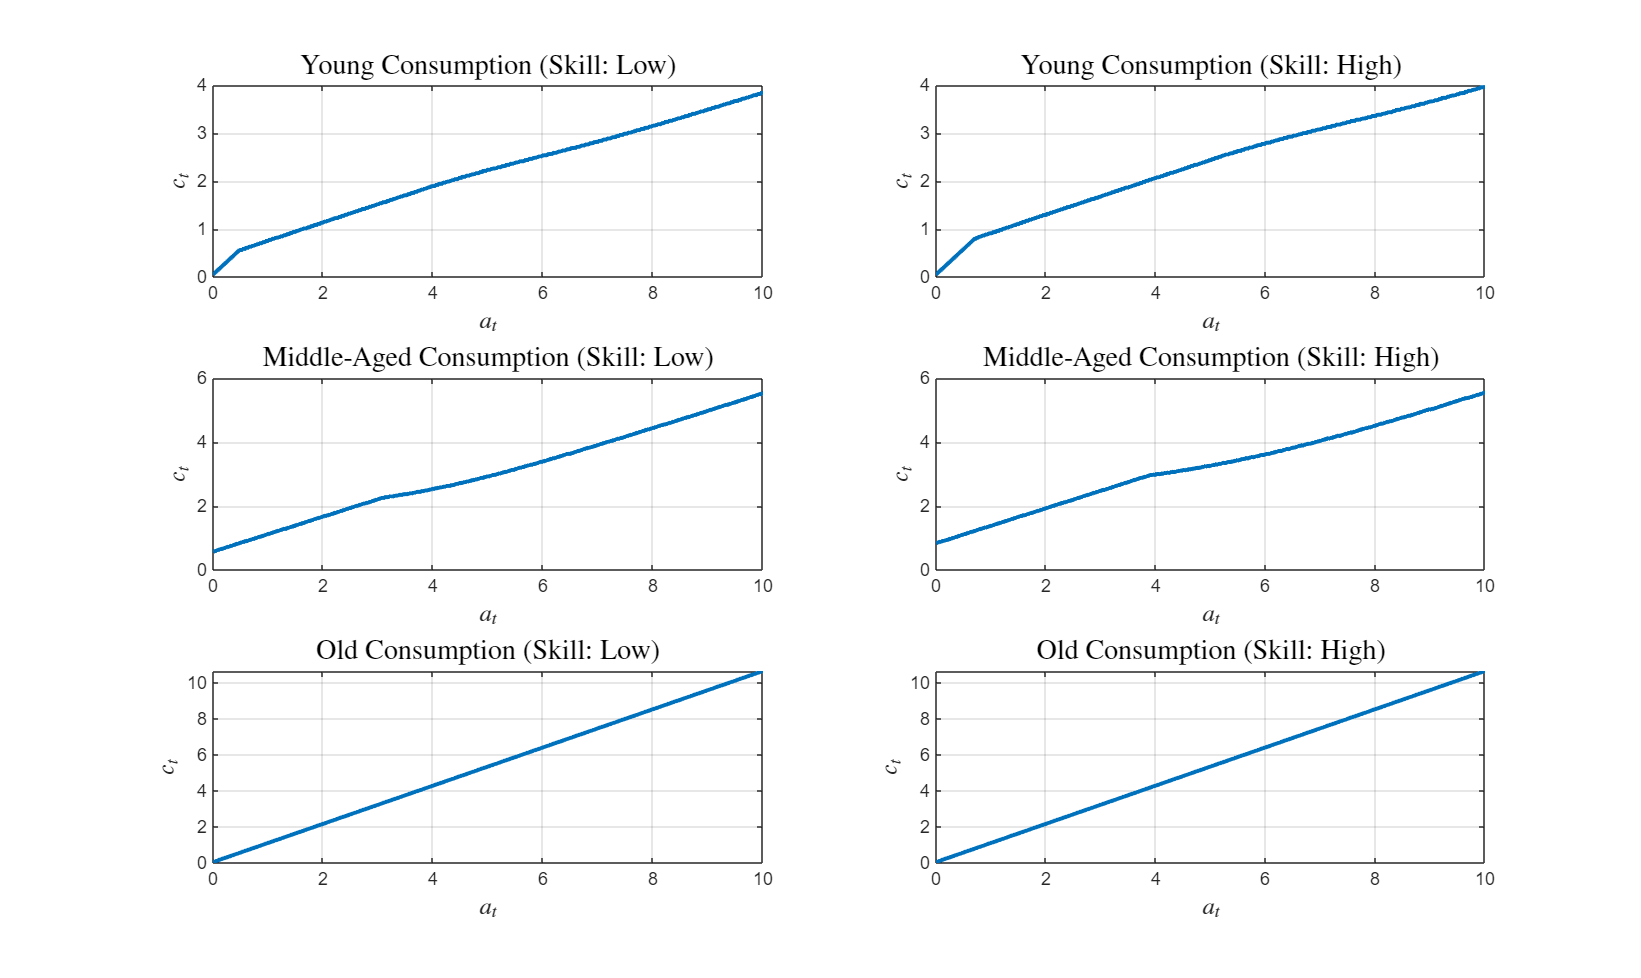

lmy_graph.cfun(par, sol, sim) % Plot the consumption function.

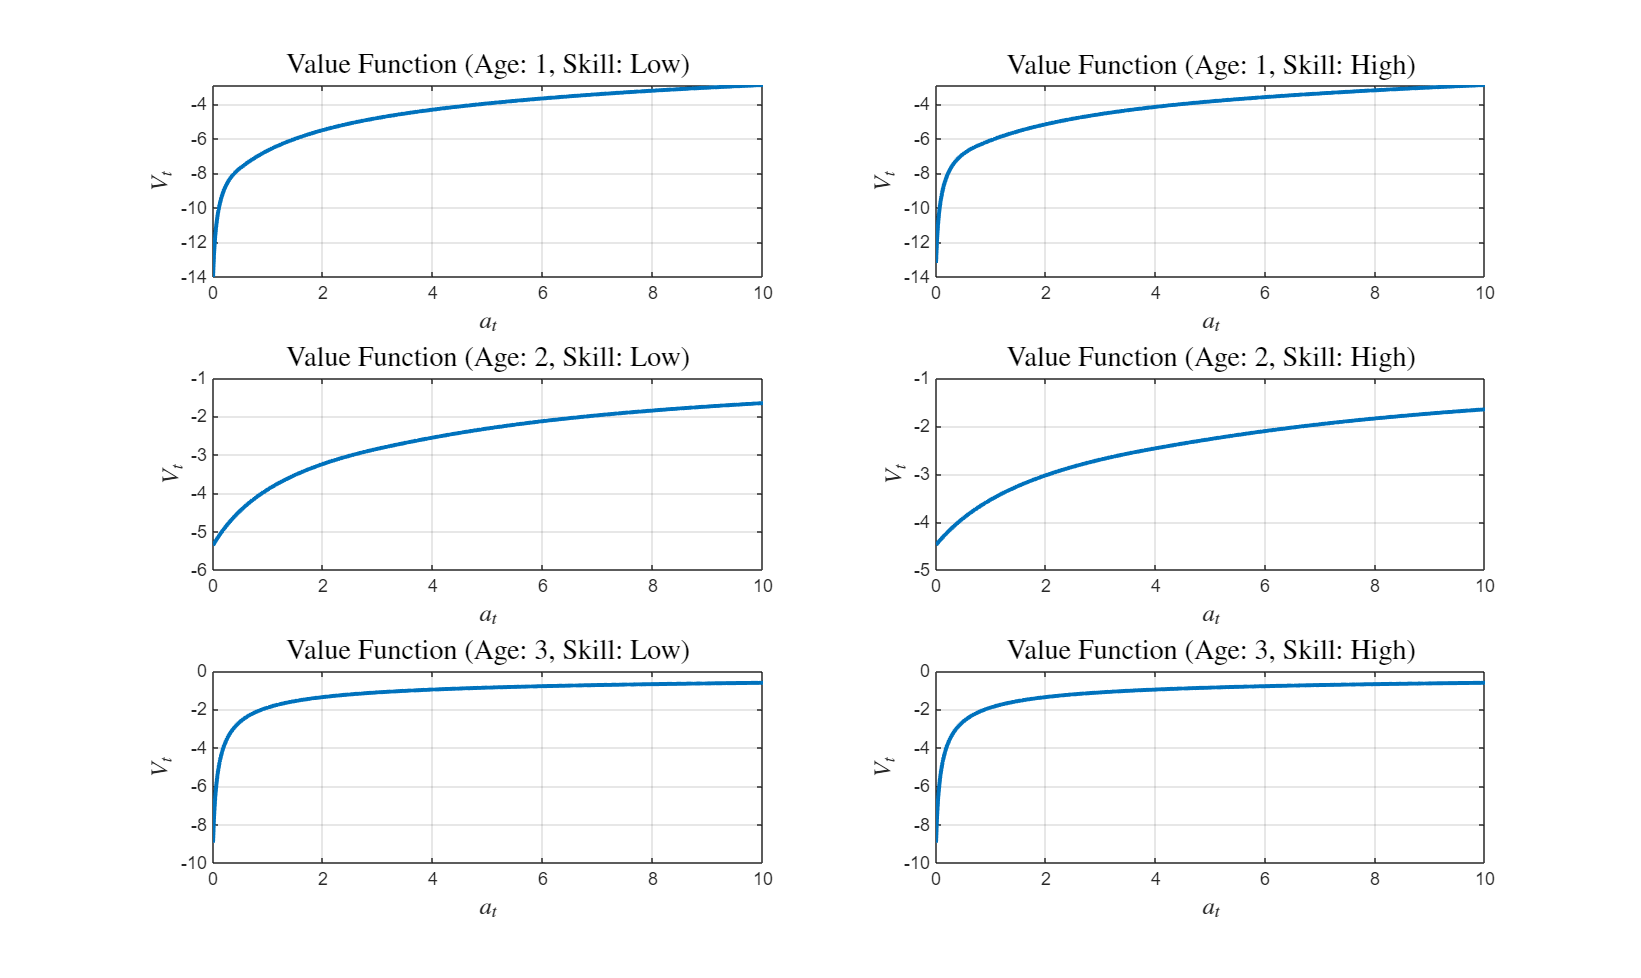

lmy_graph.vfun(par, sol, sim) % Plot the value functions.

%my_graph.plot_labor_dist(sim, par); % Plot the labor supply distribution.

% Display results
fprintf('=== Model Results ===\n')

=== Model Results ===


fprintf('Capital: %.4f\n', sol.k)

Capital: 6.9534


fprintf('Base wage: %.4f\n', par.w)

Base wage: 1.2706


%fprintf('Tax rates: tau0 = %.4f, tau1 = %.4f\n', sol.tau0, sol.tau1)
fprintf('Welfare (solve, overall): %.4f\n', sol.welfare)

Welfare (solve, overall): -1.3539


fprintf('Welfare (solve, low-skill): %.4f\n', sol.welfare_low)

Welfare (solve, low-skill): -1.3741


fprintf('Welfare (solve, high-skill): %.4f\n', sol.welfare_high)

Welfare (solve, high-skill): -1.3338


fprintf('Welfare (simulate, overall): %.4f\n', sim.welfare)

Welfare (simulate, overall): -4.6493


fprintf('Welfare (simulate, low-skill): %.4f\n', sim.welfare_low)

Welfare (simulate, low-skill): -4.7109


fprintf('Welfare (simulate, high-skill): %.4f\n', sim.welfare_high)

Welfare (simulate, high-skill): -4.5988


fprintf('Average savings (middle-aged, low-skill): %.4f\n', mean(sim.asim(2, par.skill_assign == 1)))

Average savings (middle-aged, low-skill): 0.5758


fprintf('Average savings (middle-aged, high-skill): %.4f\n', mean(sim.asim(2, par.skill_assign == 2)))

Average savings (middle-aged, high-skill): 0.6646


fprintf('Average consumption: %.4f\n', sim.csup)

Average consumption: 0.4911


fprintf('Average labor supply (middle-aged, low-skill): %.4f\n', mean(sim.lsim(2, par.skill_assign == 1)))

Average labor supply (middle-aged, low-skill): 1.0000


fprintf('Average labor supply (middle-aged, high-skill): %.4f\n', mean(sim.lsim(2, par.skill_assign == 2)))

Average labor supply (middle-aged, high-skill): 1.0000


## Solve the model in general equilibrium.

Solve the model taking prices, where prices adjust so that markets clear, then plot the distribution of wealth.

Calls: solve.m, simulate.m, my_graph.m

find_prices = @(r0)(lequilibrium.obj_fun(r0,par)); % Find the value of r that sets supply equal demand.
r_eq = fminbnd(find_prices,-par.delta,(1/par.beta)-1); % Equilibrium r.

------------Beginning Backward Induction.------------

Adjusted flat tax: tau = 0.2000
Solving for age 3
Solving for age 2
Solving for age 1
------------Backward Induction Complete.------------

Welfare (overall): -1.3325
Welfare (low-skill): -1.3565
Welfare (high-skill): -1.3085
Number of low-skill agents: 45
Number of high-skill agents: 55
Agent 1, Skill 2, Savings: 0.9619, Labor: 1.0000
Agent 2, Skill 1, Savings: 0.9619, Labor: 1.0000
Agent 3, Skill 1, Savings: 0.9619, Labor: 1.0000
Agent 4, Skill 2, Savings: 1.1824, Labor: 1.0000
Agent 5, Skill 2, Savings: 1.1824, Labor: 1.0000
Agent 6, Skill 2, Savings: 0.9619, Labor: 1.0000
Agent 7, Skill 1, Savings: 0.7816, Labor: 1.0000
Agent 8, Skill 2, Savings: 1.1824, Labor: 1.0000
Agent 9, Skill 1, Savings: 0.9619, Labor: 1.0000
Agent 10, Skill 1, Savings: 0.9619, Labor: 1.0000
Agent 11, Skill 2, Savings: 1.1824, Labor: 1.0000
Agent 12, Skill 1, Savings: 0.9619, Labor: 1.0000
Agent 13, Skill 2, Savings: 0.9619, Labor: 1.0000
Agent 14, Skill

par_ge = par;
par_ge.r = r_eq;
[par_ge,sol_ge] = lsolvewithtax.firm_problem(par_ge); % Firms.
sol_ge = lsolvewithtax.hh_problem(par_ge,sol_ge); % Households.

------------Beginning Backward Induction.------------

Adjusted flat tax: tau = 0.2000
Solving for age 3
Solving for age 2
Solving for age 1
------------Backward Induction Complete.------------

Welfare (overall): -1.3540
Welfare (low-skill): -1.3738
Welfare (high-skill): -1.3341


sol_ge = lsolvewithtax.hh_problem(par_ge,sol_ge); % Households.

------------Beginning Backward Induction.------------

Adjusted flat tax: tau = 0.2000
Solving for age 3
Solving for age 2
Solving for age 1
------------Backward Induction Complete.------------

Welfare (overall): -1.3540
Welfare (low-skill): -1.3738
Welfare (high-skill): -1.3341


sim_ge = lsimulate.economy(par_ge,sol_ge); % Simulate the economy.

Number of low-skill agents: 45
Number of high-skill agents: 55
Agent 1, Skill 2, Savings: 0.6012, Labor: 1.0000
Agent 2, Skill 1, Savings: 0.5812, Labor: 1.0000
Agent 3, Skill 1, Savings: 0.5812, Labor: 1.0000
Agent 4, Skill 2, Savings: 0.7214, Labor: 1.0000
Agent 5, Skill 2, Savings: 0.7214, Labor: 1.0000
Agent 6, Skill 2, Savings: 0.6012, Labor: 1.0000
Agent 7, Skill 1, Savings: 0.4810, Labor: 1.0000
Agent 8, Skill 2, Savings: 0.7214, Labor: 1.0000
Agent 9, Skill 1, Savings: 0.5812, Labor: 1.0000
Agent 10, Skill 1, Savings: 0.5812, Labor: 1.0000
Agent 11, Skill 2, Savings: 0.7214, Labor: 1.0000
Agent 12, Skill 1, Savings: 0.5812, Labor: 1.0000
Agent 13, Skill 2, Savings: 0.6012, Labor: 1.0000
Agent 14, Skill 1, Savings: 0.5812, Labor: 1.0000
Agent 15, Skill 2, Savings: 0.4810, Labor: 1.0000
Agent 16, Skill 2, Savings: 0.7214, Labor: 1.0000
Agent 17, Skill 1, Savings: 0.4810, Labor: 1.0000
Agent 18, Skill 1, Savings: 0.5812, Labor: 1.0000
Agent 19, Skill 2, Savings: 0.7214, Labor: 1.0

%sim_ge = simulate.economy(par_ge,sol_ge); % Simulate the economy.

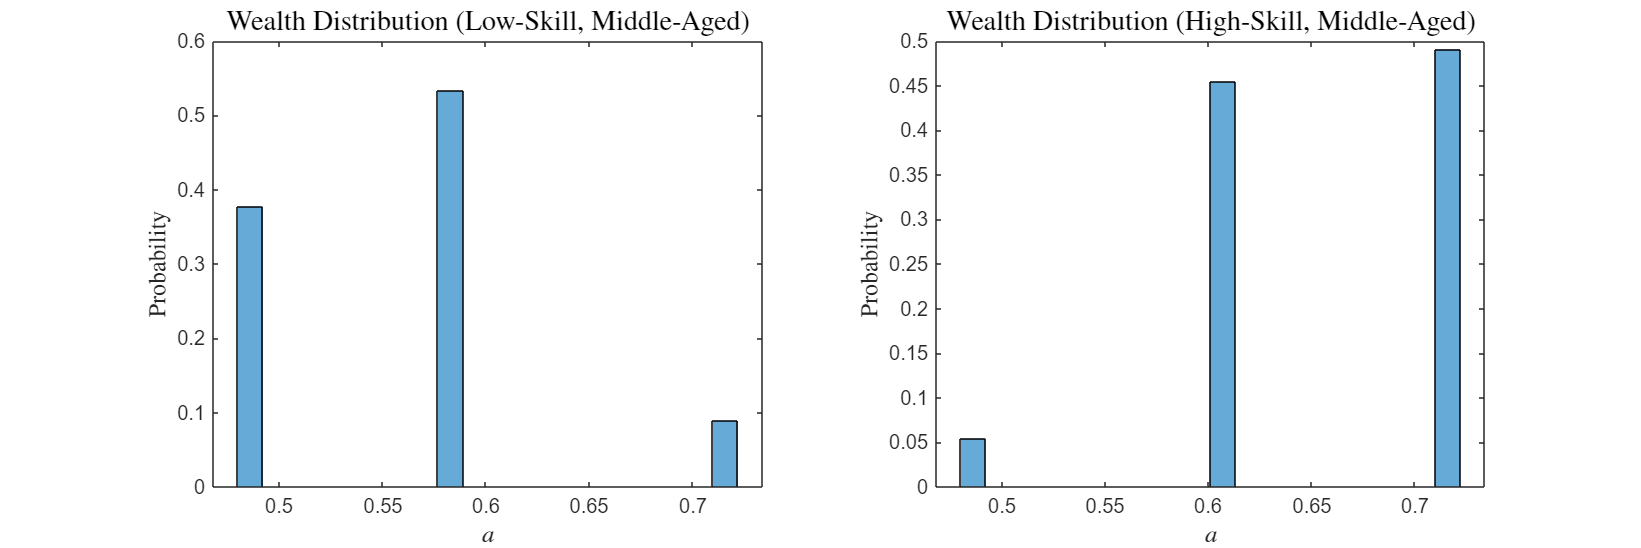

lmy_graph.plot_dist_ge(sim_ge, par_ge, sol_ge);

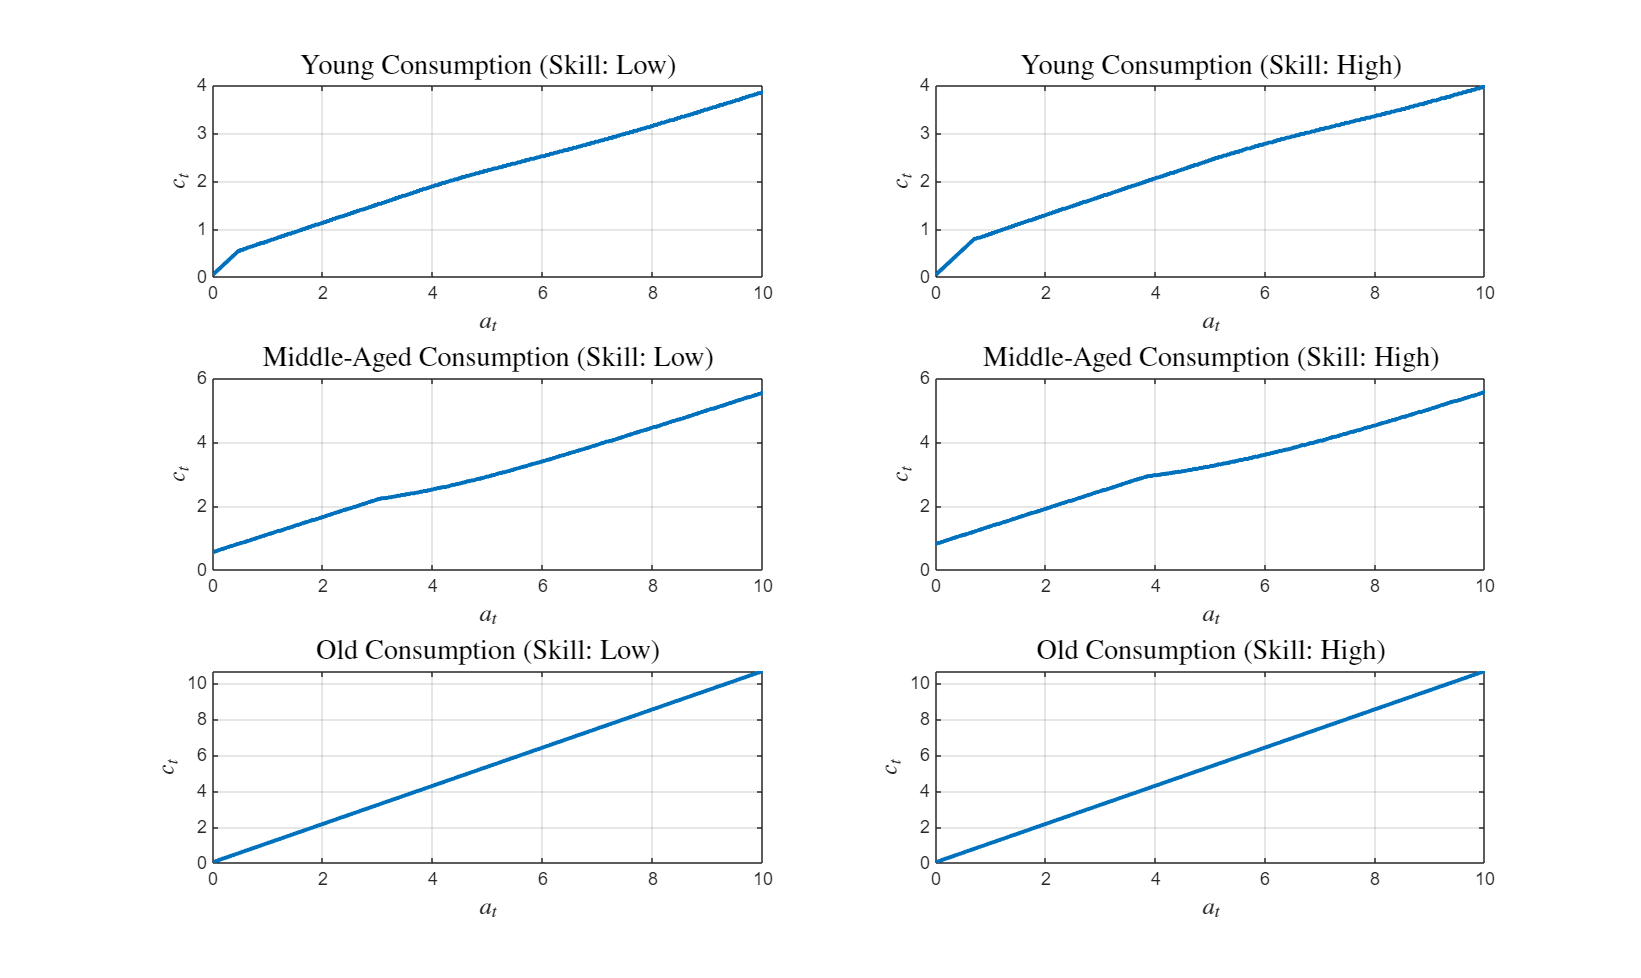

lmy_graph.cfun(par_ge,sol_ge, sim_ge);